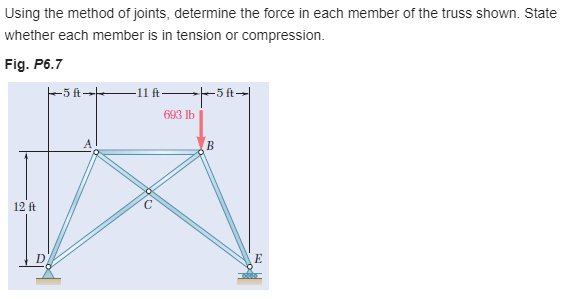

[https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-7P-solution-9780077687304](https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-7P-solution-9780077687304) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

E = sym('E');
A = sym('A');
thetaAC = atand(sym(12)/sym(16))*u.deg;
thetaCE = thetaAC;
thetaBC = thetaAC;
thetaCD = thetaAC;
thetaAD = atand(sym(12)/sym(5))*u.deg;
thetaBE = thetaAD;
jointC = 11/2*[1 -tan(thetaAC)]*u.ft;

# truss

t = Truss;
t = t.add('reaction', {'Rdx' 'Rdy'}, [-5 -12]*u.ft);
t = t.add('reaction', {0 'Rey'}, [16 -12]*u.ft);
t = t.add('concentrated', [0 -693]*u.lbf, [11 0]*u.ft);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [11 0]*u.ft);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', [-5 -12]*u.ft);
t = t.add('joint', 'E', [16 -12]*u.ft);
t = t.add('member', 'Fab', [0 0], [11 0]*u.ft);
t = t.add('member', 'Fac', [0 0], jointC);
t = t.add('member', 'Fad', [0 0], [-5 -12]*u.ft);
t = t.add('member', 'Fbc', [11 0]*u.ft, jointC);
t = t.add('member', 'Fbe', [11 0]*u.ft, [16 -12]*u.ft);
t = t.add('member', 'Fce', jointC, [16 -12]*u.ft);
t = t.add('member', 'Fcd', jointC, [-5 -12]*u.ft);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 7) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & \frac{24336.57}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{1} & -\frac{13801.9}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{2} & \frac{19716.57}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{2} & -\frac{22122.1}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{3} & \frac{20088.14}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{3} & -\frac{24049.81}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{4} & 0\\ v_{4} & 0\\ u_{5} & \frac{44688.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{5} & 0 \end{array}\right)$$

fa

$$fa = \left(\begin{array}{cc} \mathrm{Fab} & -420\,\mathrm{lbf}\\ \mathrm{Fac} & 400\,\mathrm{lbf}\\ \mathrm{Fad} & -260\,\mathrm{lbf}\\ \mathrm{Fbc} & 125\,\mathrm{lbf}\\ \mathrm{Fbe} & -832\,\mathrm{lbf}\\ \mathrm{Fcd} & 125\,\mathrm{lbf}\\ \mathrm{Fce} & 400\,\mathrm{lbf} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rdx} & 0\\ \mathrm{Rdy} & 165\,\mathrm{lbf}\\ \mathrm{Rey} & 528\,\mathrm{lbf} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa old_assum;